%smoothedData = smoothedData(:, 3:end);
%smoothedData = table2array(smoothedData);

% Apply Independent Component Analysis (ICA)
Mdl = rica(smoothedData, 12);

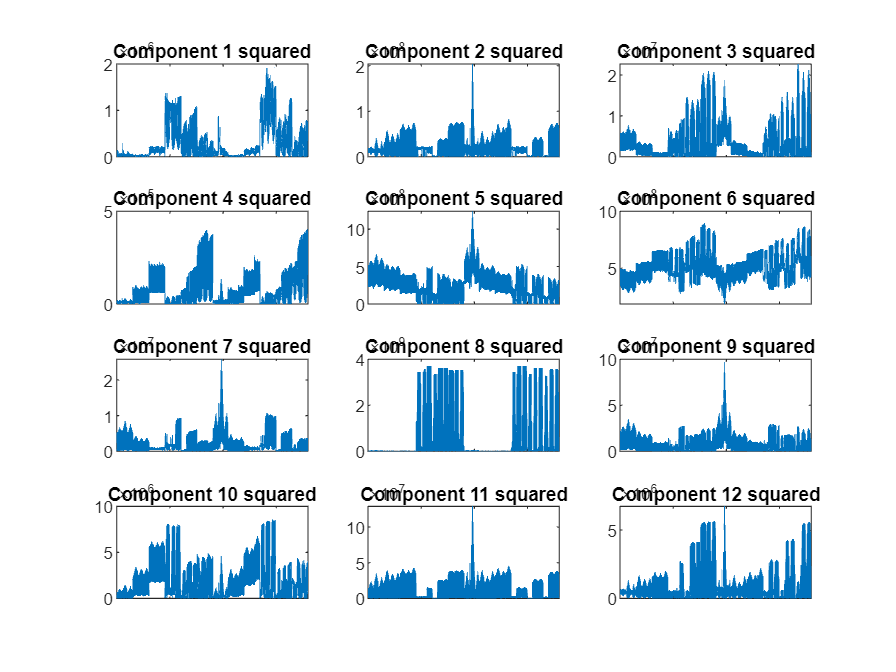

ICA_Data = transform(Mdl, smoothedData);

plotspercolumn = 4;
figure;
for i = 1:12
    subplot(plotspercolumn, ceil(12 / plotspercolumn), i)
    plot(ICA_Data(:, i).^2) % Square the components for better visualization
    title(['Component ', num2str(i), ' squared'])
    ax = gca;
    ax.XTickLabel = {};
end

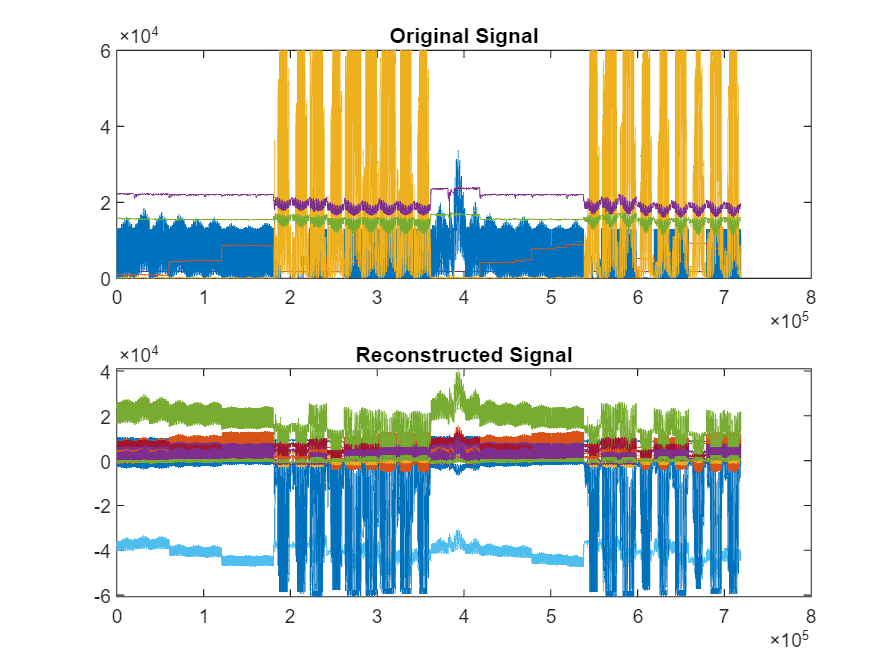


componentsToRemove = [];

% Set the coefficients of the components to be removed to zero
ICA_Data(:, componentsToRemove) = 0;

% Reconstruct the signal
reconstructedSignal = transform(Mdl, ICA_Data) * Mdl.TransformWeights';

% Plot the original and reconstructed signals
figure;
subplot(2, 1, 1);
plot(smoothedData);
title('Original Signal');

subplot(2, 1, 2);
plot(reconstructedSignal);
title('Reconstructed Signal');